# TP #09 - Ejercicio 11

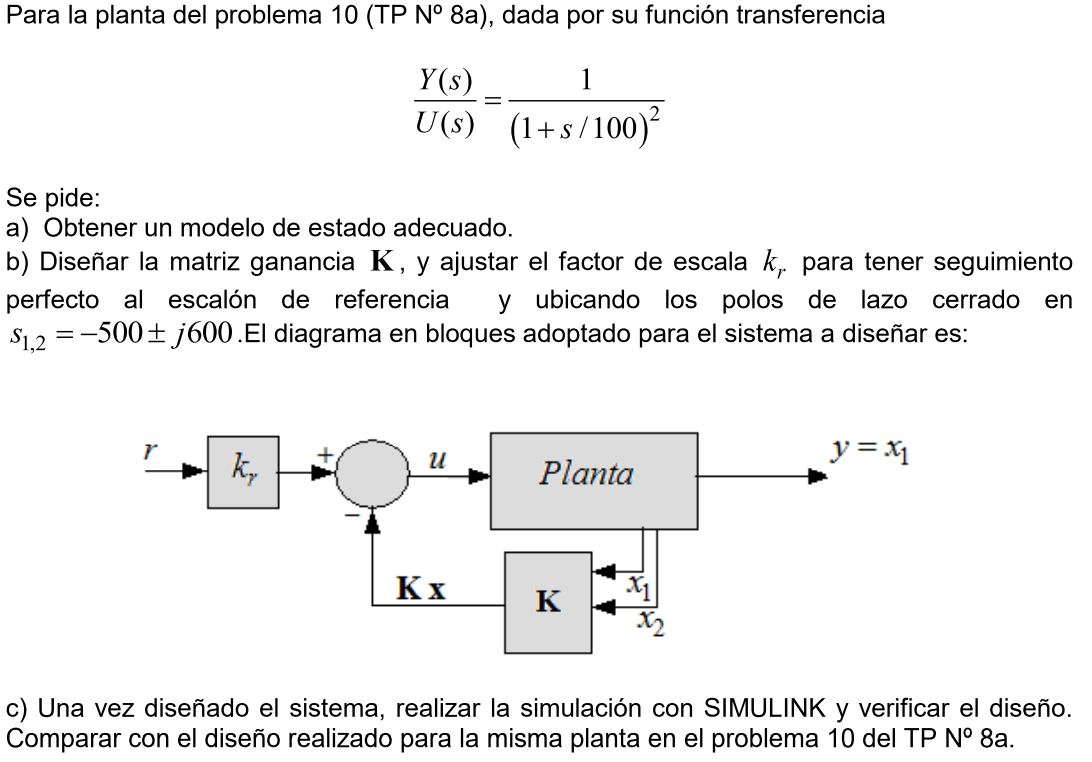

Del enunciado,


$$\begin{array}{l}
G\left(s\right)=\frac{1}{{\left(\frac{s}{100}+1\right)}^2 \;}\\
G\left(s\right)=\frac{{10}^4 }{\left(s^2 +s\;200+{10}^4 \right)}
\end{array}$$


En base al modelo canónico controlable podemos definir,


$$\left\lbrack A\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-a_0  & -a_1 
\end{array}\right\rbrack$$



$$\left\lbrack A\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-{10}^4  & -200
\end{array}\right\rbrack$$



$$\left\lbrack B\right\rbrack =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$$



$$\left\lbrack C\right\rbrack =\left\lbrack \begin{array}{cc}
\left(b_0 -b_2 a_0 \right) & \left(b_1 -b_2 a_1 \right)
\end{array}\right\rbrack$$



$$\left\lbrack C\right\rbrack =\left\lbrack \begin{array}{cc}
{10}^4  & 0
\end{array}\right\rbrack$$



$$\left\lbrack D\right\rbrack =\left\lbrack b_2 \right\rbrack$$



$$\left\lbrack D\right\rbrack =\left\lbrack 0\right\rbrack$$


Busquemos entonces la matríz 'K'


$$\begin{array}{l}
\mu \left(t\right)=r\left(t\right)k_r -K\;X\left(t\right)\\
\overset{\ldotp }{X} \left(t\right)=A\;X\left(t\right)+B\mu \left(t\right)\\
\overset{\ldotp }{X} \left(t\right)=A\;X\left(t\right)+B\left(r\left(t\right)k_r -K\;X\left(t\right)\right)\\
\overset{\ldotp }{X} \left(t\right)=\left(A-B\;K\right)X\left(t\right)+B\;r\left(t\right)k_r ;\left(\mathit{\mathbf{a}}\right)\;
\end{array}$$


Se pide, 


$$\begin{array}{l}
\textrm{PLC}:\;\left(s+500+\textrm{j600}\right)\;\left(s+500-\textrm{j600}\right)\\
\textrm{PLC}:s^2 +s\;1000+610000;\left(\mathit{\mathbf{b}}\right)
\end{array}$$



$$\begin{array}{l}
A-\textrm{BK}=\left\lbrack \begin{array}{cc}
0 & 1\\
-{10}^4  & -200
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
k_1  & k_2 
\end{array}\right\rbrack \\
A-\textrm{BK}=\;\left\lbrack \begin{array}{cc}
0 & 1\\
-{10}^4  & -200
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
0 & 0\\
k_1  & k_2 
\end{array}\right\rbrack \\
A-\textrm{BK}=\;\left\lbrack \begin{array}{cc}
0 & 1\\
-{10}^4 -k_1  & -200-k_2 
\end{array}\right\rbrack 
\end{array}$$


Finalmente hallamos la expresión de los polos deseados,


$$\begin{array}{l}
\left(\mathrm{sI}-A+\mathrm{BK}\right)=\left\lbrack \begin{array}{cc}
s & 0\\
0 & s
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
0 & 1\\
-{10}^4 -k_1  & -200-k_2 
\end{array}\right\rbrack \\
\left(\mathrm{sI}-A+\mathrm{BK}\right)=\left\lbrack \begin{array}{cc}
s & -1\\
{10}^4 +k_1  & s+200+k_2 
\end{array}\right\rbrack 
\end{array}$$


Hallamos ahora el determinante,


$$\textrm{det}\left(\textrm{sI}-A+\textrm{BK}\right)=s^2 +s\left(200+k_2 \right)+k_1 +{10}^4$$


Reemplazando con lo hallado en **(b)**

- 
$$k_1 =600000$$


- 
$$k_2 =800$$


Podemos además corroborar con la función 'acker'

A = [0 1; -1e4 -200];
B = [0; 1];
C = [1e4 0];
D = [];
PLC=[-500+600i -500-600i];
disp('Ganancias calculadas con Ackerman:')

Ganancias calculadas con Ackerman:


K=acker(A,B,PLC)

K =       600000         800


disp('Vector de Realimentción de Estados ([An]):')

Vector de Realimentción de Estados ([An]):


An=A-B*K

An =            0           1
     -610000       -1000


disp('Posición diseñada de los polos a lazo cerrado:')

Posición diseñada de los polos a lazo cerrado:


PLC_d=eig(An)

PLC_d = 	1.0e+02 *

  -5.0000 + 6.0000i
  -5.0000 - 6.0000i


Finalmente hallamos el valor de $k_r$, partiendo de **(a)**,


$$\overset{\ldotp }{X} \left(t\right)=\left(A-B\;K\right)X\left(t\right)+B\;r\left(t\right)k_r$$


Aplicamos transformada de Laplace, y con condiciones iniciales nulas


$$\textrm{sX}\left(s\right)-X\left(0\right)=\left(A-B\;K\right)X\left(s\right)+B\;R\left(s\right)k_r$$



$$\textrm{sX}\left(s\right)-\left(A-B\;K\right)X\left(s\right)=B\;R\left(s\right)k_r$$



$$\left(\textrm{sI}-A+B\;K\right)X\left(s\right)=B\;R\left(s\right)k_r$$



$$X\left(s\right)={\left(\textrm{sI}-A+B\;K\right)}^{-1} B\;R\left(s\right)k_r$$


Tomando la ecuación de la salida,


$$Y\left(s\right)\;=\;C\;X\left(s\right)$$



$$Y\left(s\right)={C\left(\textrm{sI}-A+B\;K\right)}^{-1} B\;R\left(s\right)k_r$$


Como vamos a excitar al sistema con una señal escalón, podemos analizar el teorema de valor final, suponiendo,


$$\lim_{s\to 0} \;s\;Y\left(s\right)\;=1$$



$$\lim_{s\to 0} \;s\;C\;{\left(s\;I-A+B\;K\right)}^{-1} B\;\frac{1}{s}k_r \;=1$$



$$\lim_{s\to 0} \;C\;{\left(s\;I-A+B\;K\right)}^{-1} B\;k_r \;=1$$



$$C\;{\left(-A+B\;K\right)}^{-1} B\;k_r \;=1$$



$$\;k_r \;=\frac{1}{C{\left(-A+B\;K\right)}^{-1} B}$$


Empleando MATLab para evitar el cálculo matricial,

kr = 1/(C*inv(-A+B*K)*B)

kr = 61

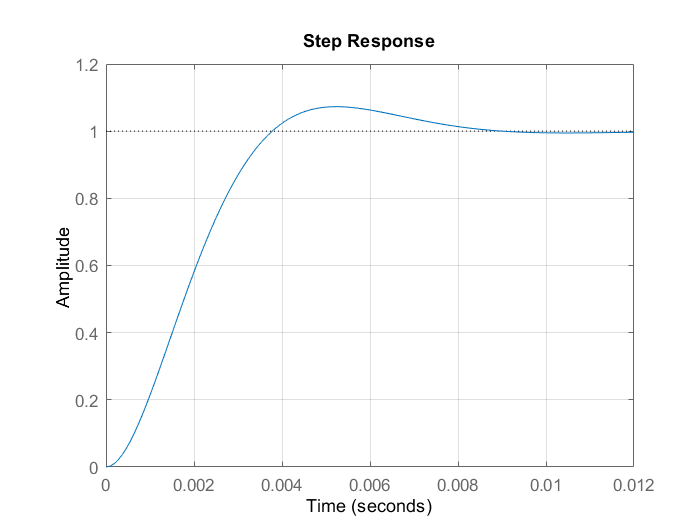

sys=ss(An,B*kr,C,D);
step(sys)
grid on;

Simulink, ejecutar ***TP09_ej11.slx.***